# AAE 575 - Homework 4

## Setup and Constants

% LATEX Interpreter for Plots
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);
set(groot, 'defaultAxesTickLabelInterpreter',interr);
set(groot, 'defaultLegendInterpreter',interr);

addpath('hw4_data_2021b')
fL1 = 1575.42e6; fL2 = 1227.6e6; % carrier freq, Hz
freq = [fL1 fL2];
c = 299792458; % speed of light, m/s
lamL1 = c/fL1; lamL2 = c/fL2; % carrier wavelength, m/cycle
PRDU18 = load('rawdata.PRDU.sv18'); % location A
PRDU15 = load('rawdata.PRDU.sv15');
INWL18 = load('rawdata.INWL.sv18'); % location B
INWL15 = load('rawdata.INWL.sv15');
orbit18 = load('orbit.sv18'); % sat 2
orbit15 = load('orbit.sv15'); % sat 1
gpstime = PRDU18(:,1);

## Problem 1

% Double Differences for L1 and L2
[phase_ddiff_L1, prange_ddiff_L1] = doublediff(PRDU15,PRDU18,INWL15,INWL18,'L1')

phase_ddiff_L1 = 	1.0e+03 *

   -4.6348
   -4.5957
   -4.5567
   -4.5176
   -4.4785
   -4.4395
   -4.4005
   -4.3614
   -4.3223
   -4.2833


prange_ddiff_L1 =  -888.1000
 -880.6800
 -873.2400
 -865.8200
 -858.3400
 -850.8400
 -843.3200
 -835.8000
 -828.3600
 -820.9000


[phase_ddiff_L2, prange_ddiff_L2] = doublediff(PRDU15,PRDU18,INWL15,INWL18,'L2')

phase_ddiff_L2 = 	1.0e+03 *

   -3.6049
   -3.5745
   -3.5440
   -3.5136
   -3.4832
   -3.4527
   -3.4223
   -3.3918
   -3.3614
   -3.3310


prange_ddiff_L2 =  -887.6600
 -880.3600
 -873.0000
 -865.5000
 -858.0200
 -850.5800
 -843.1400
 -835.7400
 -828.3600
 -820.9800


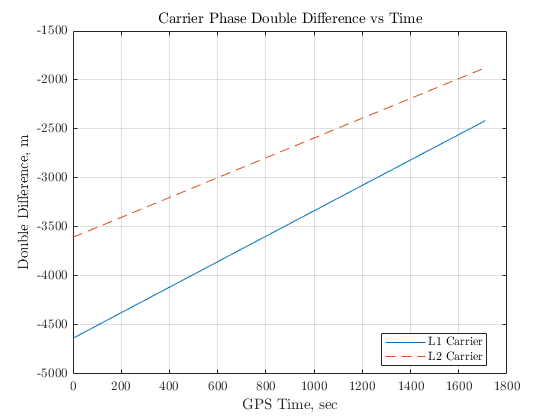


plot(gpstime,phase_ddiff_L1)
hold on
plot(gpstime,phase_ddiff_L2,'--')
title('Carrier Phase Double Difference vs Time')
xlabel('GPS Time, sec')
ylabel('Double Difference, m')
legend('L1 Carrier','L2 Carrier','Location',"best")
grid on
hold off

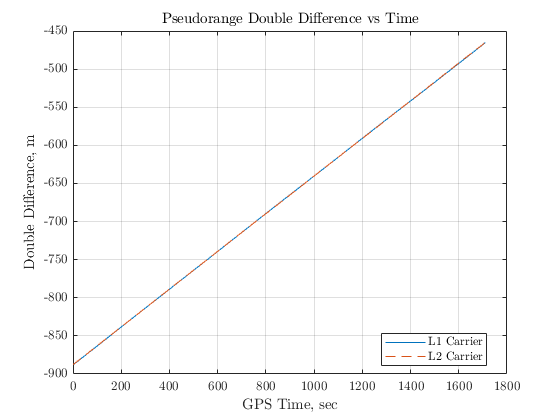


plot(gpstime,prange_ddiff_L1)
hold on
plot(gpstime,prange_ddiff_L2,'--')
title('Pseudorange Double Difference vs Time')
xlabel('GPS Time, sec')
ylabel('Double Difference, m')
legend('L1 Carrier','L2 Carrier','Location',"best")
grid on
hold off

## Problem 2

% L1 Integer Ambiguity
ambi_L1 = phase_ddiff_L1 - prange_ddiff_L1/lamL1;
plot(gpstime,ambi_L1)
hold on
ambi_L1 = round(sum(ambi_L1)/length(ambi_L1))

ambi_L1 = 30

% L2 Integer Ambiguity
ambi_L2 = phase_ddiff_L2 - prange_ddiff_L2/lamL2;
plot(gpstime,ambi_L2)
ambi_L2 = round(sum(ambi_L2)/length(ambi_L2))

ambi_L2 = 30

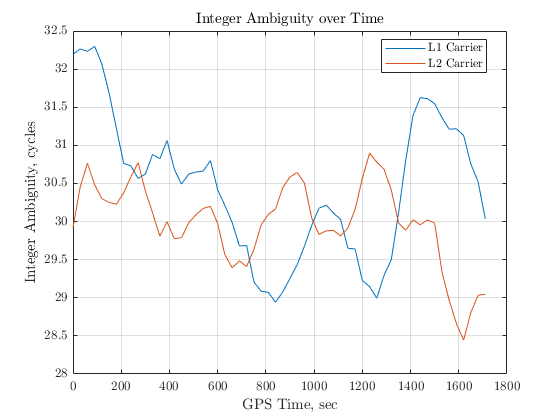

ambi = [ambi_L1, ambi_L2];
title('Integer Ambiguity over Time')
xlabel('GPS Time, sec')
ylabel('Integer Ambiguity, cycles')
legend('L1 Carrier','L2 Carrier','Location',"best")
grid on
hold off

## Problem 3

% Carrier Phase Range Estimate, L1 Carrier
phase_range_L1 = -lamL1 * (phase_ddiff_L1 - ambi_L1)

phase_range_L1 =   887.6823
  880.2492
  872.8149
  865.3827
  857.9472
  850.5199
  843.0874
  835.6547
  828.2209
  820.7924



% Carrier Phase Range Estimate, L2 Carrier
phase_range_L2 = -lamL2 * (phase_ddiff_L2 - ambi_L2)

phase_range_L2 =   887.6792
  880.2484
  872.8129
  865.3826
  857.9471
  850.5185
  843.0847
  835.6483
  828.2167
  820.7913



% True Range
PRDUloc = [262004.574, -4855113.867, 4114363.877]; % loc A
INWLloc = [260604.167, -4853018.976, 4116926.580]; % loc B
r12_true = PRDUloc - INWLloc

r12_true = 	1.0e+03 *

    1.4004   -2.0949   -2.5627



for i = 1:length(orbit18)
    u1_true(i,:) = (orbit18(i,2:4)-PRDUloc)/norm(orbit18(i,2:4)-PRDUloc); % unit vector to sat 1
    u2_true(i,:) = (orbit15(i,2:4)-PRDUloc)/norm(orbit15(i,2:4)-PRDUloc); % unit vector to sat 2
    r12AB_true(i,:) = dot(u2_true(i,:)-u1_true(i,:),r12_true);
end
error_L1 =  phase_range_L1 - r12AB_true

error_L1 =     0.0795
    0.0810
    0.0808
    0.0824
    0.0800
    0.0852
    0.0848
    0.0835
    0.0804
    0.0820


error_L2 =  phase_range_L2 - r12AB_true

error_L2 =     0.0764
    0.0802
    0.0789
    0.0822
    0.0799
    0.0839
    0.0821
    0.0771
    0.0763
    0.0809


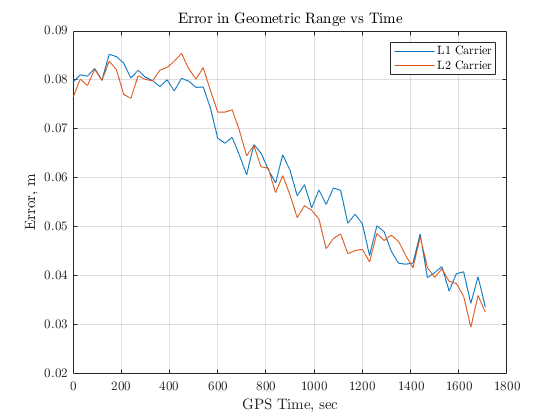


% Plots
plot(gpstime,error_L1)
hold on
plot(gpstime,error_L2)
grid on
title('Error in Geometric Range vs Time')
xlabel('GPS Time, sec')
ylabel('Error, m')
legend('L1 Carrier','L2 Carrier')
hold off

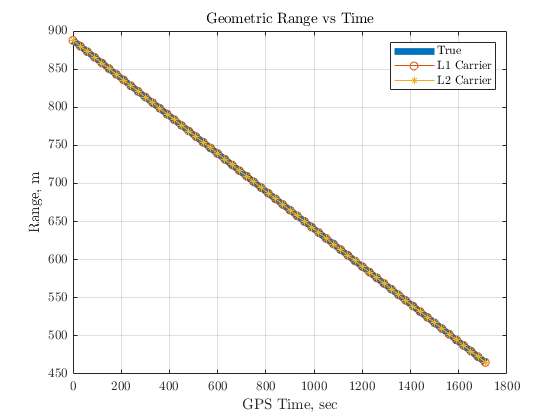


plot(gpstime,r12AB_true,'LineWidth',5)
hold on
plot(gpstime,phase_range_L1,'o-','Markersize',6)
plot(gpstime,phase_range_L2,'*-','Markersize',5)
grid on
title('Geometric Range vs Time')
xlabel('GPS Time, sec')
ylabel('Range, m')
legend('True','L1 Carrier','L2 Carrier')
hold off


bias_L1 = mean(error_L1)

bias_L1 = 0.0617

bias_L2 = mean(error_L2)

bias_L2 = 0.0608

std_L1 = std(error_L1)

std_L1 = 0.0161

std_L2 = std(error_L2)

std_L2 = 0.0174

## Functions

#### Function 1: Double Differences

function [cdiff,pdiff] = doublediff(sat1A, sat2A, sat1B, sat2B,carrier)
% Finds the double difference for the Carrier Phase and the Pseudorange

if eq(carrier,'L1')
    p = 2; c = 4;
elseif eq(carrier,'L2')
    p = 3; c = 5;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Carrier Phase Double Difference
% Location A
phase1A = sat1A(:,c); % carrier phase for sat 1
phase2A = sat2A(:,c); % carrier phase for sat 2
% Location B
phase1B = sat1B(:,c); % carrier phase for sat 1
phase2B = sat2B(:,c); % carrier phase for sat 2

% Single Differences
sin_diff1 = phase1B - phase1A; 
sin_diff2 = phase2B - phase2A;

% Double Difference
cdiff = sin_diff2 - sin_diff1;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pseudorange Double Difference
% Location A
prange1A = sat1A(:,p); % prange for sat 1
prange2A = sat2A(:,p); % prnage for sat 2

% Location B
prange1B = sat1B(:,p); % prange for sat 1
prange2B = sat2B(:,p); % prnage for sat 2

% Single Differences
sin_diff1 = prange1A - prange1B;
sin_diff2 = prange2A - prange2B;

% Double Difference
pdiff = sin_diff1 - sin_diff2;
end